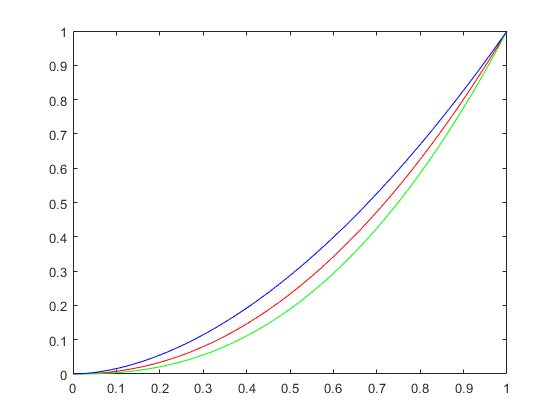

%1.1
load('TRC_display.mat');
y = 0:0.01:1;
plot(y,TRCr,'r');
hold on
plot(y,TRCg,'g');
plot(y,TRCb,'b');
hold off

%Green gets lighter faster than red, red faster than blue (?)

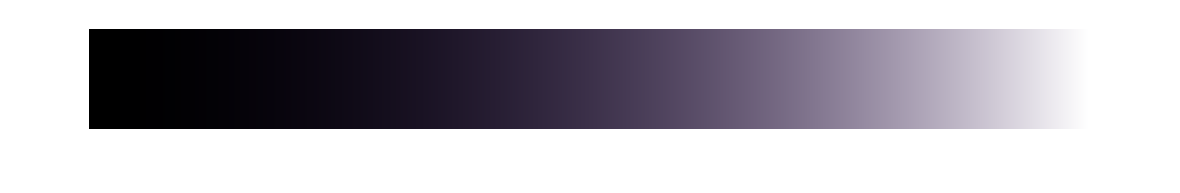

%1.2
load('Ramp_display.mat')
load('Ramp_linear.mat')

imshow(Ramp_display)

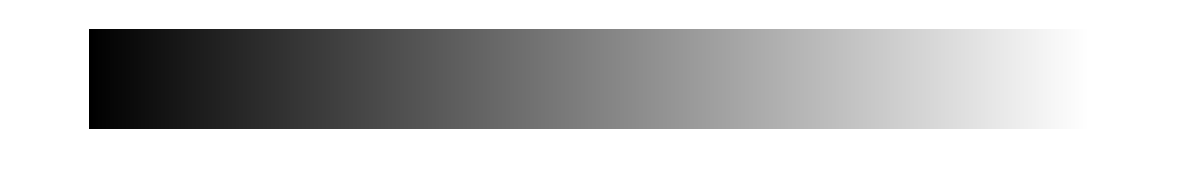

%imshow(Ramp_linear)

linearized_ramp = linearization(Ramp_display, TRCr, TRCg, TRCb);
imshow(linearized_ramp)

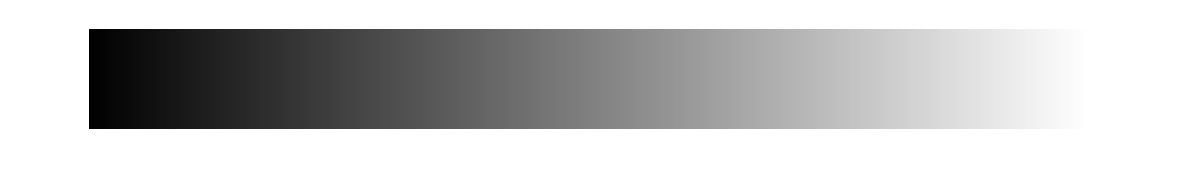

%1.3
gammaR = 2.1;
gammaG = 2.4;
gammaB = 1.8;

Dmax = max(max(Ramp_display));
D(:,:,1) = Dmax(:,:,1) .* (Ramp_display(:,:,1)./Dmax(:,:,1)).^(1/gammaR);
D(:,:,2) = Dmax(:,:,2) .* (Ramp_display(:,:,2)./Dmax(:,:,2)).^(1/gammaG);
D(:,:,3) = Dmax(:,:,3) .* (Ramp_display(:,:,3)./Dmax(:,:,3)).^(1/gammaB);
imshow(D)

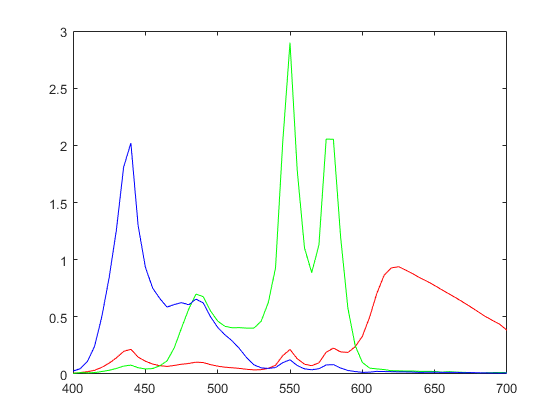

%2.1
load('DLP.mat');
wavelengths = 400:5:700;

plot(wavelengths, DLP(:,1), 'r');
hold on
plot(wavelengths, DLP(:,2), 'g');
plot(wavelengths, DLP(:,3), 'b');
hold off

%green is incredibly wide in range, red is similar to lab 1, 
% blue is wide but not as intense.
%green also has a strange dip at around 565 


%2.2
load('RGB_raw.mat');
load('xyz.mat');
load('illum.mat');
load('XYZ_ref.mat');


SRGB =  DLP*RGB_raw;
k = 100/sum(CIED65'.*xyz(:,2));
XYZ_SRGB=k*SRGB'*xyz;
XYZ_SRGB = XYZ_SRGB';

[lc,ac,bc] = xyz2lab(XYZ_SRGB(1,:),XYZ_SRGB(2,:),XYZ_SRGB(3,:));
[lr,ar,br] = xyz2lab(XYZ_ref(1,:),XYZ_ref(2,:),XYZ_ref(3,:));
diff = sqrt((lc-lr).^2 +(ac-ar).^2 +(bc-br).^2);
maxVal = max(diff)

maxVal = 51.6380

meanVal = mean(diff)

meanVal = 22.3508

%2.3
load('RGB_cal.mat')

SRGB =  DLP*RGB_cal;
k = 100/sum(CIED65'.*xyz(:,2));
XYZ_SRGB=k*SRGB'*xyz;
XYZ_SRGB = XYZ_SRGB';

[lc,ac,bc] = xyz2lab(XYZ_SRGB(1,:),XYZ_SRGB(2,:),XYZ_SRGB(3,:));
[lr,ar,br] = xyz2lab(XYZ_ref(1,:),XYZ_ref(2,:),XYZ_ref(3,:));
diff = sqrt((lc-lr).^2 +(ac-ar).^2 +(bc-br).^2);
maxVal = max(diff)

maxVal = 33.5351

meanVal = mean(diff)

meanVal = 16.9236



%Bättre, my guy. Since they are calibrated there isn't as huge of a
%difference etc etc.


%3.1

Acrt = xyz'*DLP;
k = 100/sum(CIED65'.*xyz(:,2));
Acrt_cal = k*Acrt

Acrt_cal =    38.0922   55.7160   19.9274
   22.6080   87.9484   11.4011
   10.9203   16.5373   92.4433


%3.2
load('XYZ_est.mat');

DD = inv(Acrt_cal)*XYZ_est;

SRGB =  DLP*DD;
k = 100/sum(CIED65'.*xyz(:,2));
XYZ_SRGB=k*SRGB'*xyz;
XYZ_SRGB = XYZ_SRGB';

[lc,ac,bc] = xyz2lab(XYZ_SRGB(1,:),XYZ_SRGB(2,:),XYZ_SRGB(3,:));
[lr,ar,br] = xyz2lab(XYZ_ref(1,:),XYZ_ref(2,:),XYZ_ref(3,:));
diff = sqrt((lc-lr).^2 +(ac-ar).^2 +(bc-br).^2);
maxVal = max(diff)

maxVal = 3.1053

meanVal = mean(diff)

meanVal = 1.0238


%they be great

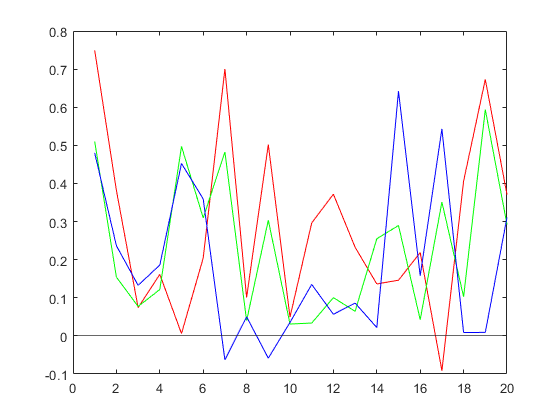

%3.3
plot(DD(1,:), 'r');
hold on
plot(DD(2,:), 'g');
plot(DD(3,:), 'b');
yline(0);
hold off

%negative values, because of the fact that it is an estimation (?)

%3.4
DD(DD > 1.0) = 1.0;
DD(DD < 0.0) = 0.0;

SRGB =  DLP*DD;
k = 100/sum(CIED65'.*xyz(:,2));
XYZ_SRGB=k*SRGB'*xyz;
XYZ_SRGB = XYZ_SRGB';

[lc,ac,bc] = xyz2lab(XYZ_SRGB(1,:),XYZ_SRGB(2,:),XYZ_SRGB(3,:));
[lr,ar,br] = xyz2lab(XYZ_ref(1,:),XYZ_ref(2,:),XYZ_ref(3,:));
diff = sqrt((lc-lr).^2 +(ac-ar).^2 +(bc-br).^2);
maxVal = max(diff)

maxVal = 17.8740

meanVal = mean(diff)

meanVal = 2.8360

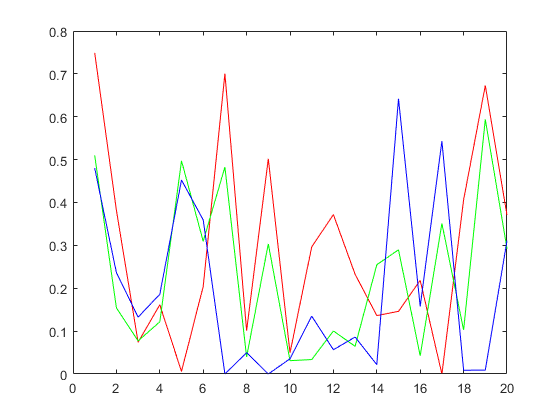


plot(DD(1,:), 'r');
hold on
plot(DD(2,:), 'g');
plot(DD(3,:), 'b');
yline(0);
hold off

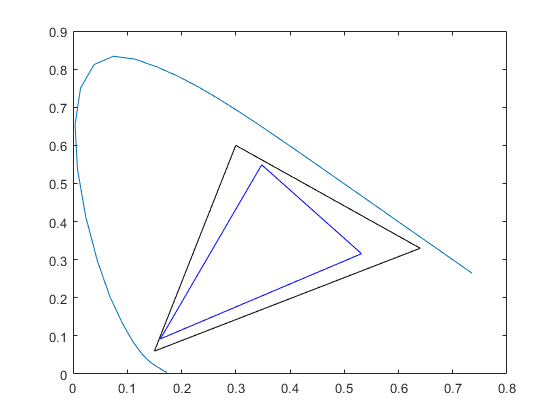

%3.5
plot_chrom_sRGB(Acrt_cal)
hold off

%Our gamut is rather small, values in the blue area are fairly good, but
%red is horrible and green is more towards a yellow than it should be and
%is therefore affected the worst. (Comparing with 1.1 it makes sense)

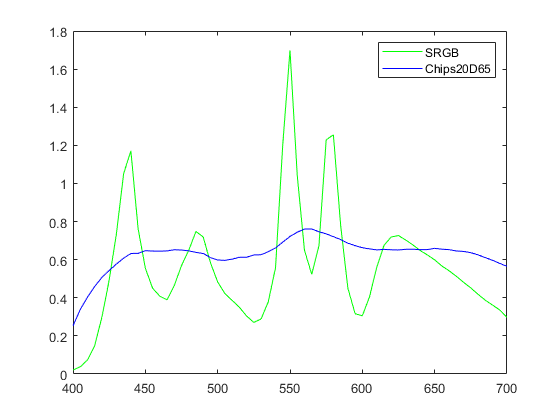

%3.6
load('chips20')

plot(400:5:700,SRGB(:,1), 'g')
hold on
plot(400:5:700,chips20(1,:).*CIED65, 'b');
legend('SRGB','Chips20D65')


%bygger på metamerism, integrering ger väldigt lika värden, omöjligt
%återskapa samma spektrum, så likt xyz-> lab som möjligt, delta e under
%ett, svårt att *se* skillnaden, men mätning i spektrum gör det tydligt pga
%fler kanaler.